# Home work 1                                               (15-Jan-2019)

t = randn(1000000,1)*pi;

x = sin(t);
y = sin(2*t);

## Histograms

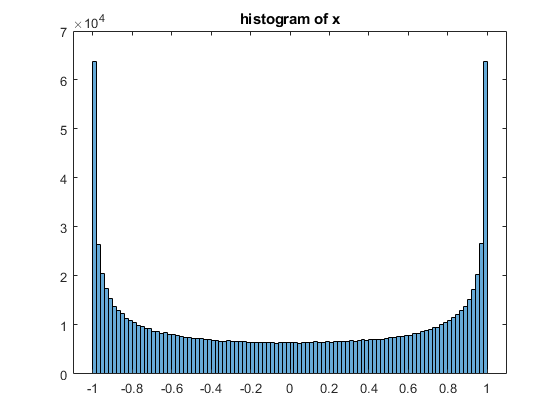

histogram(x);
title('histogram of x');

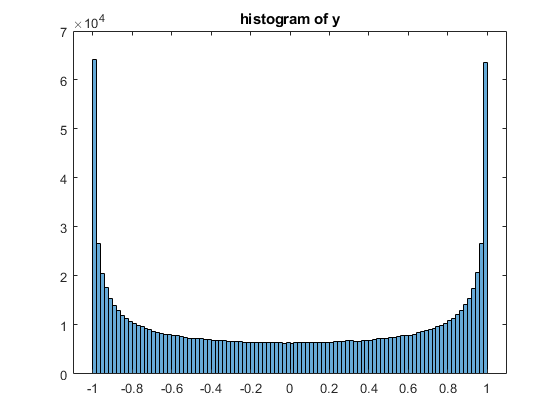

histogram(y);
title('histogram of y')

## Probability density density

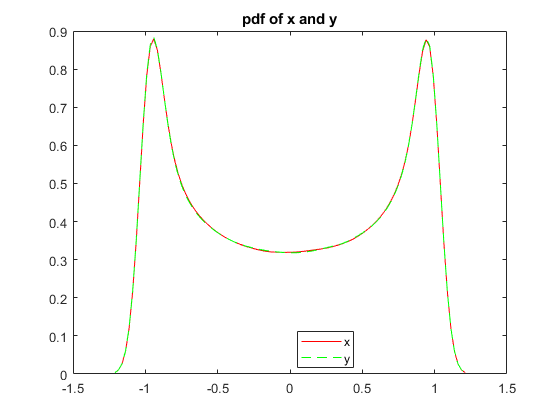

[f_x,xi] = ksdensity(x);
[f_y,yi] = ksdensity(y);

plot(xi, f_x, 'r', yi, f_y, '--g');
legend({'x', 'y'}, 'Location','best');
title('pdf of x and y');

## Joint Histogram

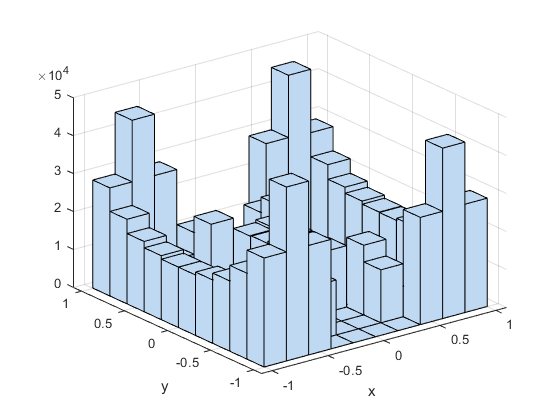

hist3([x,y]);
xlabel('x');
ylabel('y');

## Joint Probability function

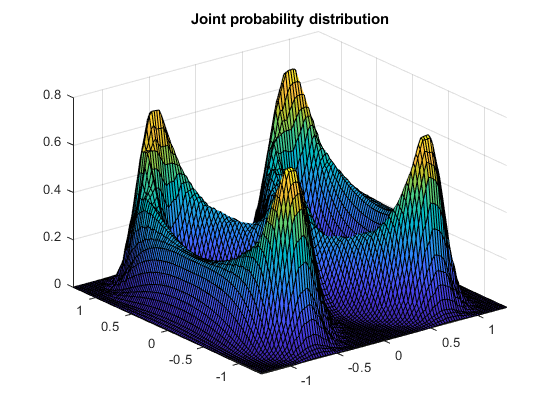

ksdensity([x,y]);
title('Joint probability distribution');

## Correlation

[R,p] = corrcoef(x,y, 'Alpha',0.05);
R

R =     1.0000    0.0082
    0.0082    1.0000


p =     1.0000    0.0000
    0.0000    1.0000


p
